## Оценка параметров реального китайского привода по данным из csv файла 

### Читаем CSV файл

clear; clc;
% csv = readmatrix("csv/rchi_step_test.csv");
csv = readmatrix("csv/rchi_6v_test.csv");
% csv = readmatrix("csv/chi_step_test.csv");

crop = 10;
data_length = length(csv(:,2))-1 - crop

data_length = 433

% data_length = 2500
time = csv(2:data_length+1, 2);    % мкс
% q_orig = csv(2:data_length+1, 3) * pi/180;  % рад
% w_orig = csv(2:data_length+1, 4) * pi/180;  % рад/c
% dw_orig = csv(2:data_length+1, 5) * pi/180;  % рад/c^2
input = csv(2:data_length+1, 6) / 100 * 6;    % В
current = csv(2:data_length+1, 7) - 0.048;  % А

q_orig = csv(2:data_length+1, 3);  % рад
w_orig = csv(2:data_length+1, 4);  % рад/c
dw_orig = csv(2:data_length+1, 5);  % рад/c^2

t_start = time(1);
time = (time - t_start)/1000000;    % с
tf = time(data_length);

dt_sum = 0;
for k = 2:data_length
    dt = time(k) - time(k-1);
    dt_sum = dt_sum + dt;
end

dt = dt_sum/(data_length-1)

dt = 0.0100


w_orig = smooth(w_orig, 6);
dw_orig = smooth(dw_orig, 50);
current = smooth(current, 10);

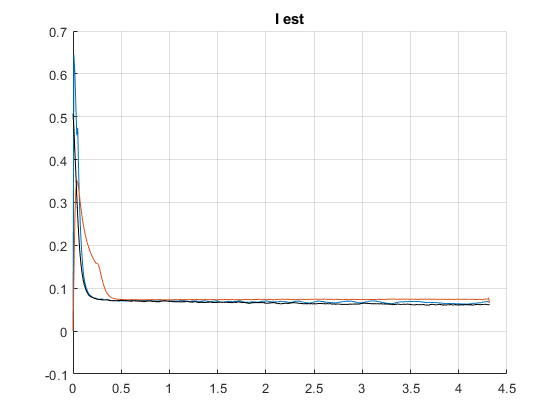

Km = 0.2923;
% Kw = -0.2923;
Kw = 0.2923*0.79;
Lam = 0.0019*0.5;
J = 0.0011*0.5;
% J = 1.3872e-04;
R = 11.8227;
% Lam = 0.0019;
% J = 0.0011;
% R = 11.8227;
M_ext_orig = J*dw_orig + Lam*w_orig - Km*current;
I_est_orig = J*dw_orig/Km + Lam*w_orig/Km;
I_est_orig_u = (input - Kw*w_orig)/R;

figure;
hold on
plot(time, current)
plot(time, I_est_orig)
plot(time, I_est_orig_u, "black")
hold off
title("I est")
xlim("auto")
ylim("auto")
grid on

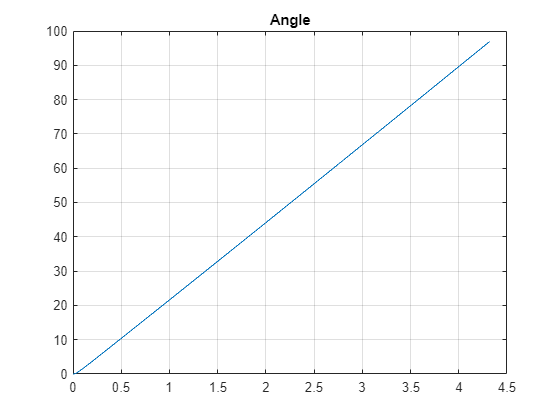

figure;
plot(time, q_orig)
title("Angle")
xlim("auto")
ylim("auto")
grid on

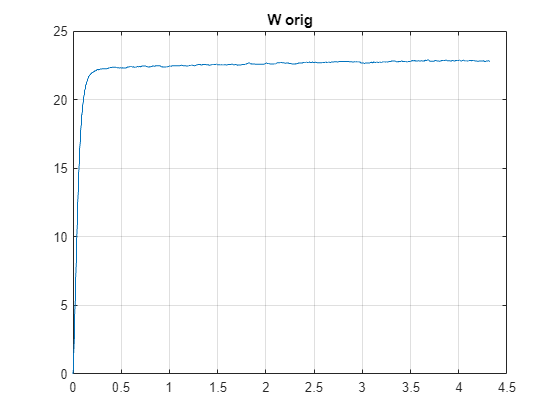


figure;
plot(time, w_orig)
title("W orig")
xlim("auto")
ylim("auto")
grid on

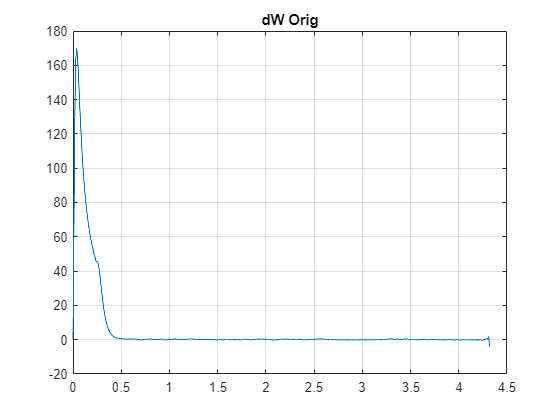


figure;
plot(time, dw_orig)
title("dW Orig")
xlim("auto")
ylim("auto")
grid on

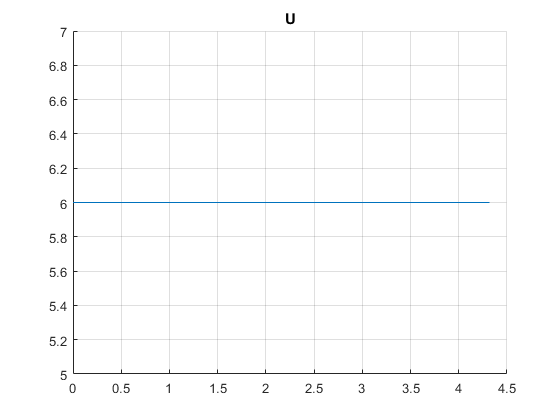


figure;
hold on
plot(time, input)
% plot(time, w_orig)
hold off
title("U")
xlim("auto")
ylim("auto")
grid on

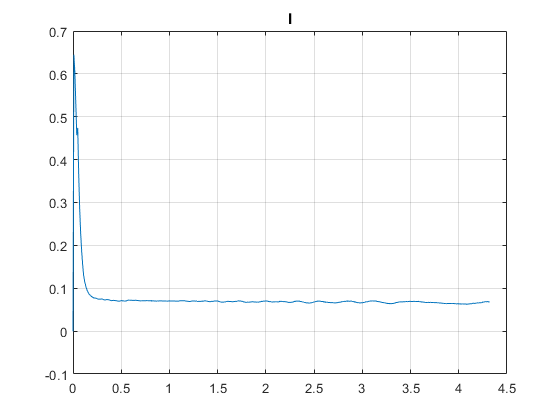


figure;
plot(time, current)
title("I")
xlim("auto")
ylim("auto")
grid on

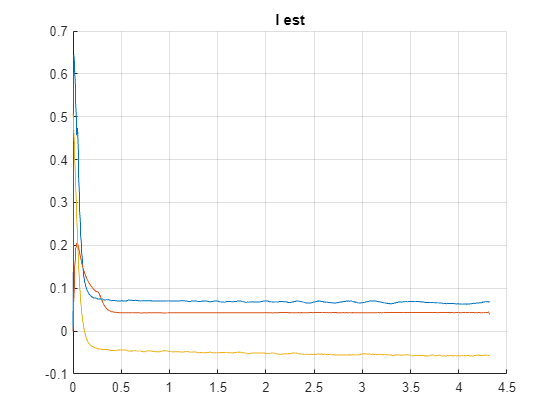


figure;
hold on
plot(time, current)
plot(time, I_est_orig)
plot(time, I_est_orig_u)
hold off
title("I est")
xlim("auto")
ylim("auto")
grid on

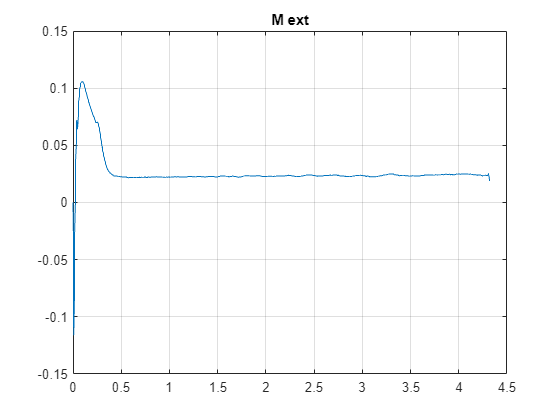


figure;
plot(time, M_ext_orig)
title("M ext")
xlim("auto")
ylim("auto")
grid on

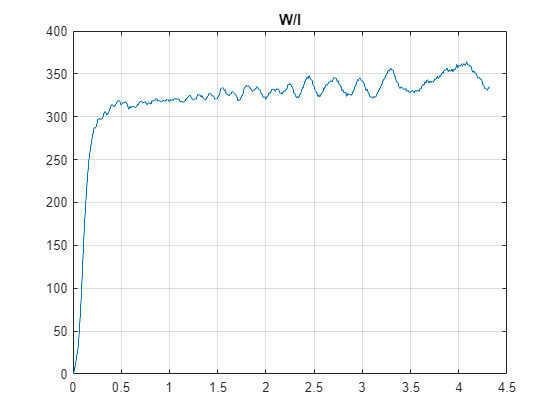


figure;
% plot(time, input./current)
plot(time, w_orig./current)
% title("U/I")
title("W/I")
xlim("auto")
ylim("auto")
% ylim([10 15])
grid on

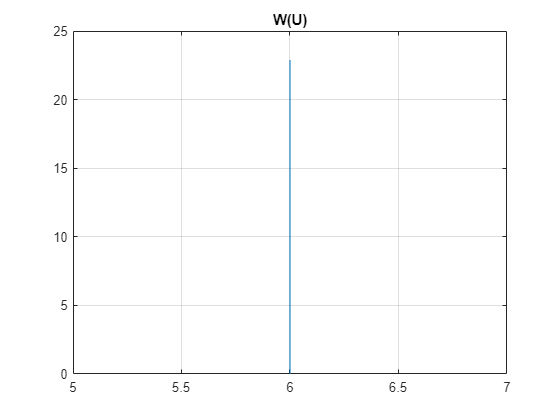


figure;
plot(input, w_orig)
% title("W/U")
title("W(U)")
xlim("auto")
ylim("auto")
% ylim([10 15])
grid on

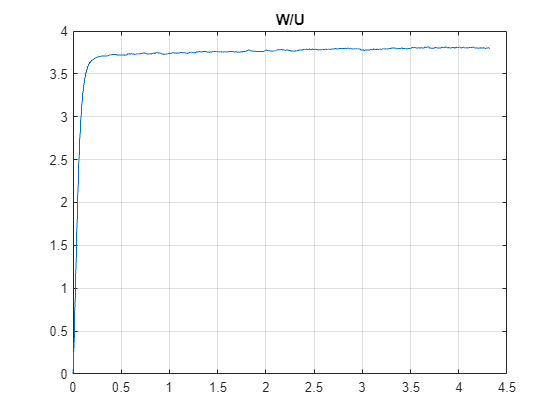


figure;
plot(time, w_orig./input)
title("W/U")
xlim("auto")
ylim("auto")
% ylim([10 15])
grid on

% start = 3500;
% finish = 3550;

start = 1;
finish = 50;

figure;
plot(time(start:finish), q_orig(start:finish), '*-')
% plot(time(start:finish), ticks(start:finish))
title("Q")
xlim("auto")
ylim("auto")
grid on

figure;
plot(time(start:finish), w_orig(start:finish), '*-')
title("W")
xlim("auto")
ylim("auto")
grid on

figure;
plot(time(start:finish), dw_orig(start:finish), '*-')
title("B")
xlim("auto")
ylim("auto")
grid on

figure;
% plot(time(start:finish), current(start:finish), '*-')
plot(time(start:finish), current(start:finish))
title("I")
xlim("auto")
ylim("auto")
grid on

figure;
hold on
% plot(time(start:finish), input(start:finish), '*-')
plot(time(start:finish), input(start:finish))
plot(time(start:finish), w_orig(start:finish))
hold off
title("U")
xlim("auto")
ylim("auto")
grid on

### Parameters identification with kalman filter model with load

% from offline parameter identification with KF MAXON
L = 1.0551;
R = 5.9043;
Kw = 1.9437;
Km = 1.9437;
J = 0.0085;
Lam = 0.0020;

% from offline parameter identification CHI
L = 0.0876;
R = 19.5747;
Kw = 0.2254;
Km = 0.2254;
J = 0.0004;
Lam = 0.0021; 

% from offline parameter identification CHI + KF (better)
L = 0.0241;
R = 19.7430;
Kw = 0.2203;
Km = 0.2203;
J = 0.0005;
Lam = 0.0019; 

L = 0.0314;
J = 0.0011;
R = 11.8227;
Kw = 0.2923;
Km = Kw;
Lam = 0.0019; 

% L = 0.0314;
% J = 0.0011;
% R = 11.8227*16;
% Km = 0.2923;
% Kw = -Km;
% Lam = 0.0019; 
    
% random
% L = rand();
% R = rand();
% Kw = rand();
% Km = rand();
% J = rand();
% Lam = rand();

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L];
B = [1/J 0;
     0   Km/(J*L);
     0   1/L];
C = eye(3);
D = [0 0 0]';

C_lqe = [1 0 0;
         0 1 0;
         0 0 0];
[Te, De] = eig(A);
% Cc = ctrb(A,B)
% Cob = obsv(A, C_lqe)
% rank(Cc)
% rank(Cob)

Vd_w = 1e2;
Vd_dw = 1e3;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [1e1 0 0;
      0 1e7 0;
      0 0 1];

% dt = 0.01
dt

dt = 0.0100

[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, dt);
Kf

Kf =     0.9109   -0.0000         0
   -4.1250    0.0808         0
   -0.0172    0.0000         0


% "<< " + Kf(1,1) + ", " + Kf(1,2) + ", " + Kf(1,3) + ", " ...
%       + Kf(2,1) + ", " + Kf(2,2) + ", " + Kf(3,3) + ", " ...
%       + Kf(3,1) + ", " + Kf(3,2) + ", " + Kf(3,3)

betta = 0.3; % коэффициент регуляризации
k0 = 2; % начальное значение матрицы коэффициентов
% betta = 7 % коэффициент регуляризации
% k0 = 600 % начальное значение матрицы коэффициентов
I = eye(3); % диагональная единичная матрица
GAMMA_0 = k0.*I; % матрица начальных значений коэффициентов
% GAMMA_0(3,3) = 50;

Th_hat = [0; 0; 0];
Th_hat(1) = R;
Th_hat(2) = Kw;
Th_hat(3) = Lam;
Th_hat;
Th_hat_start = Th_hat

Th_hat_start =    11.8227
    0.2923
    0.0019


dTh_hat = [0; 0; 0];

G_hat = GAMMA_0

G_hat =      2     0     0
     0     2     0
     0     0     2


dG_hat = zeros(3, 3);

% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);
Mext = 0;
Mext_arr = zeros(1, data_length);

At = expm(A*dt);
Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B;
Bt = real(Bt);
A_hat = (At-Kf*C_lqe);
B_hat = [Bt Kf];
% "<< " + At(1,1) + ", " + At(1,2) + ", " + At(1,3) + ", " ...
%       + At(2,1) + ", " + At(2,2) + ", " + At(3,3) + ", " ...
%       + At(3,1) + ", " + At(3,2) + ", " + At(3,3)
% "<< " + Bt(1,1) + ", " + Bt(1,2) + ", " ...
%       + Bt(2,1) + ", " + Bt(2,2) + ", " ...
%       + Bt(3,1) + ", " + Bt(3,2)

k_di = 0.9;
Mext_sum = 0;
% Mext = 7e-3;

for k = 2:20
% for k = 2:data_length
    dt = time(k) - time(k-1);
    u_act = input(k-1);

%     Mext = M_ext_orig(k);

    u = [Mext input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
%     u = [0 input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
    x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
    x_arr(:, k) = real(x_arr(:, k));
    
%     w_act = x_arr(1, k-1);
%     dw_act = x_arr(2, k-1);
%     I_act = x_arr(3, k-1);
%     dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;

    w_act = w_orig(k-1);
    dw_act = dw_orig(k-1);
    I_act = current(k-1);
    dI_act = (current(k)-current(k-1))/dt;

    dI_arr(k) = dI_arr(k-1)*(1-k_di) + k_di*dI_act;
    q_arr(k) = q_arr(k-1) + w_act*dt;

    % Mext = J*dw + Lam*w - Km*I
%     Mext = Th_hat(4)*x_arr(2, k) + Th_hat(5)*x_arr(1,k) - Th_hat(3)*x_arr(3,k);
%     Mext = J*x_arr(2,k) + Lam*x_arr(1,k) - Km*x_arr(3,k);
    Mext = J*x_arr(2,k) + Th_hat(3)*x_arr(1,k) - Th_hat(2)*x_arr(3,k);
%     Mext = -Th_hat(4)*dw_act - Th_hat(5)*w_act + Th_hat(3)*I_act;
%     Mext = 1.95e-3;
    Mext_arr(k) = real(Mext);
    Mext_sum = Mext_sum + Mext;

    phi = [I_act  0;
           w_act  -I_act;
           0  w_act];
     phi_T = phi';

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;

%     U = [u_act; 0];
    U = [u_act; Mext];

    Aa = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * Aa;
   
    Th_hat = Th_hat + dTh_hat * dt;   
end

% Mext_avr = Mext_sum/data_length

Th_hat_start

Th_hat_start =    11.8227
    0.2923
    0.0019


Th_hat

Th_hat =    11.6963
    0.1895
    0.0221


eR = Th_hat(1)

eR = 11.6963

eKw = Th_hat(2)

eKw = 0.1895

eLam = Th_hat(3)

eLam = 0.0221

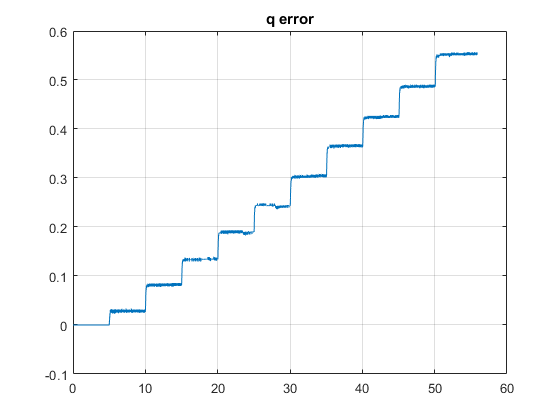

start = 1;
% finish = 500;
finish = data_length;

figure
plot(time(start:finish), (q_orig(start:finish)'-real(q_arr(start:finish))))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

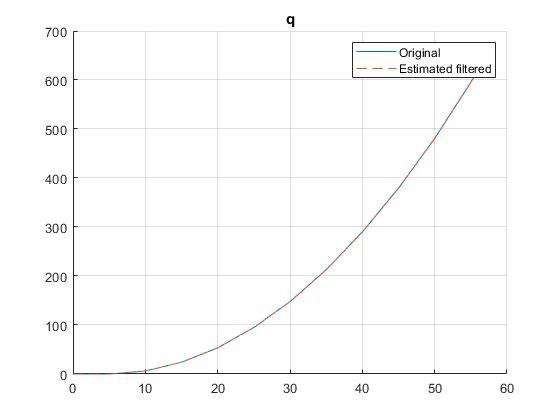


% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time(start:finish), q_orig(start:finish))
plot(time(start:finish), q_arr(start:finish), "--")
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

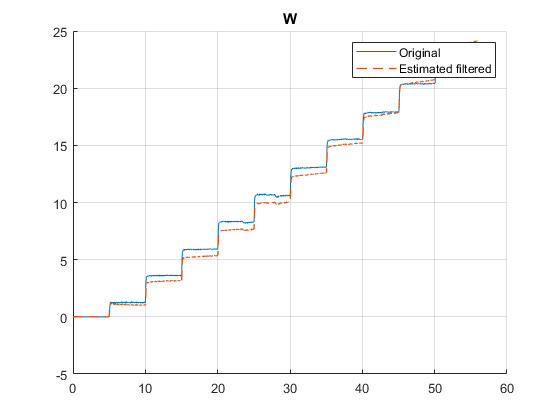


figure
hold on
plot(time(start:finish), w_orig(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 1, "LineStyle", "--")
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

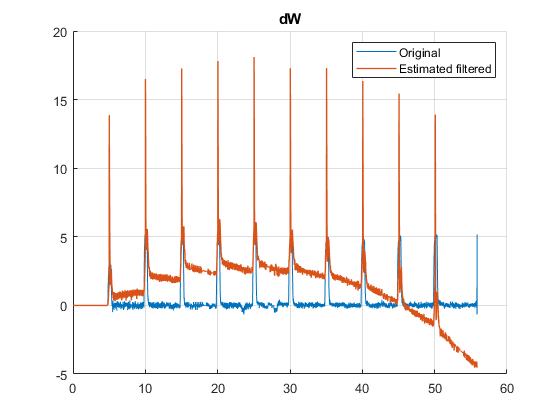


figure
hold on
plot(time(start:finish), dw_orig(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)), "LineWidth", 1)
hold off
grid on
title("dW")
xlim("auto")
ylim("auto")
% ylim([-60 60])
legend("Original", "Estimated filtered")

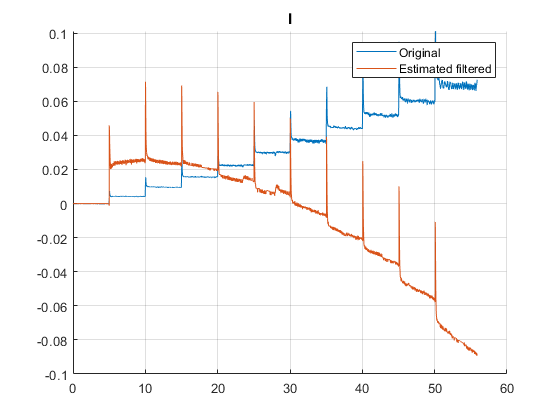


figure
hold on
plot(time(start:finish), current(start:finish))
plot(time(start:finish), x_arr(3, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

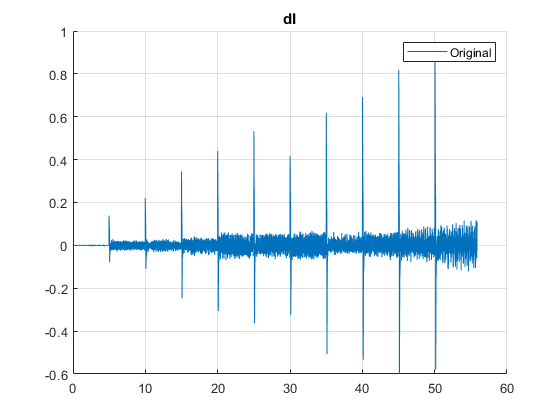


figure
hold on
plot(time(start:finish), dI_arr(start:finish))
hold off
grid on
title("dI")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

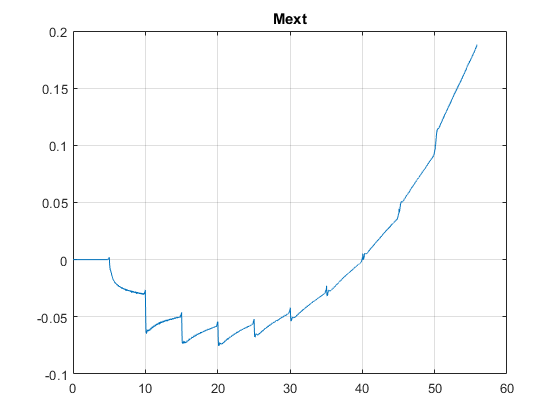


figure
plot(time, Mext_arr)
grid on
title("Mext")
xlim("auto")
ylim("auto")

### Parameters identification with kalman filter model with load

L = 0.0314;
J = 0.0011;
R = 11.8227;
Kw = 0.2923;
Km = Kw;
Lam = 0.0019; 

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L];
B = [1/J 0;
     0   Km/(J*L);
     0   1/L];
C = eye(3);
D = [0 0 0]';

C_lqe = [1 0 0;
         0 1 0;
         0 0 0];
[Te, De] = eig(A);
% Cc = ctrb(A,B)
% Cob = obsv(A, C_lqe)
% rank(Cc)
% rank(Cob)

Vd_w = 1e2;
Vd_dw = 1e2;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [1 0 0;
      0 1 0;
      0 0 1];

% dt = 0.01
dt

dt = 0.0100

[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, dt);
Kf

Kf =     0.9469   -0.0089         0
   -0.0089    0.9981         0
   -0.0081    0.0021         0



betta = 0.3; % коэффициент регуляризации
k0 = 2; % начальное значение матрицы коэффициентов
% betta = 7 % коэффициент регуляризации
% k0 = 600 % начальное значение матрицы коэффициентов
I = eye(5); % диагональная единичная матрица
GAMMA_0 = k0.*I; % матрица начальных значений коэффициентов

Th_hat = [0; 0; 0; 0; 0];
Th_hat(1) = L;
Th_hat(2) = R;
Th_hat(3) = Kw;
Th_hat(3) = Km;
Th_hat(4) = J;
Th_hat(5) = Lam;
Th_hat

Th_hat =     0.0314
   11.8227
    0.2923
    0.0011
    0.0019


Th_hat_start = Th_hat;
dTh_hat = [0; 0; 0; 0; 0];

G_hat = GAMMA_0

G_hat =      2     0     0     0     0
     0     2     0     0     0
     0     0     2     0     0
     0     0     0     2     0
     0     0     0     0     2


dG_hat = zeros(5,5)

dG_hat =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);
Mext = 0;
Mext_arr = zeros(1, data_length);

At = expm(A*dt);
Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B;
Bt = real(Bt);
A_hat = (At-Kf*C_lqe);
B_hat = [Bt Kf];

k_di = 0.9;
Mext_sum = 0;
% Mext = 7e-3;

for k = 2:data_length
    dt = time(k) - time(k-1);
    u_act = input(k-1);

%     u = [-Mext input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
    u = [0 input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
    x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
    x_arr(:, k) = real(x_arr(:, k));
    
%     w_act = x_arr(1, k-1);
%     dw_act = x_arr(2, k-1);
%     I_act = x_arr(3, k-1);
%     dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;

    w_act = w_orig(k-1);
    dw_act = dw_orig(k-1);
    I_act = current(k-1);
    dI_act = (current(k)-current(k-1))/dt;

    dI_arr(k) = dI_arr(k-1)*(1-k_di) + k_di*dI_act;
    q_arr(k) = q_arr(k-1) + w_act*dt;

    % Mext = J*dw + Lam*w - Km*I
%     Mext = Th_hat(4)*x_arr(2, k) + Th_hat(5)*x_arr(1,k) - Th_hat(3)*x_arr(3,k);
%     Mext = J*x_arr(2,k) + Lam*x_arr(1,k) - Km*x_arr(3,k);
    Mext = J*x_arr(2,k) + Th_hat(3)*x_arr(1,k) - Th_hat(2)*x_arr(3,k);
%     Mext = -Th_hat(4)*dw_act - Th_hat(5)*w_act + Th_hat(3)*I_act;
%     Mext = 1.95e-3;
    Mext_arr(k) = real(Mext);
    Mext_sum = Mext_sum + Mext;

    phi = [dI_act 0;
           I_act  0;
           w_act -I_act;
           0 dw_act;
           0 w_act];
     phi_T = phi';

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;

    U = [u_act; 0];
%     U = [u_act; -Mext];

    Aa = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * Aa;
   
    Th_hat = Th_hat + dTh_hat * dt;   
end

% Mext_avr = Mext_sum/data_length

Th_hat_start

Th_hat_start =     0.0314
   11.8227
    0.2923
    0.0011
    0.0019


Th_hat

Th_hat =     0.0914
    8.7246
    0.2353
    0.0005
    0.0007


eL = Th_hat(1);
eR = Th_hat(2);
eKw = Th_hat(3)

eKw = 0.2353

eKm = Th_hat(3);
eJ = Th_hat(4);
eLam = Th_hat(5);

start = 1;
% finish = 500;
finish = data_length;

figure
plot(time(start:finish), (q_orig(start:finish)'-real(q_arr(start:finish))))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

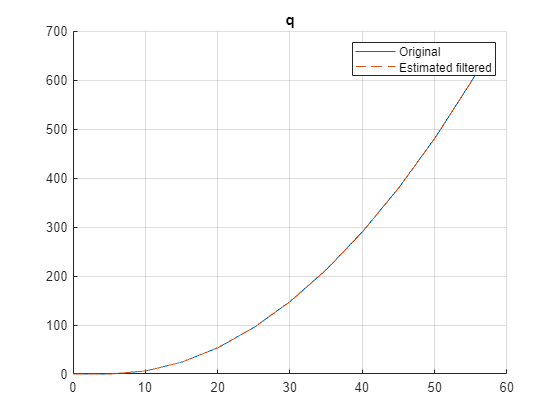


% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time(start:finish), q_orig(start:finish))
plot(time(start:finish), q_arr(start:finish), "--")
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

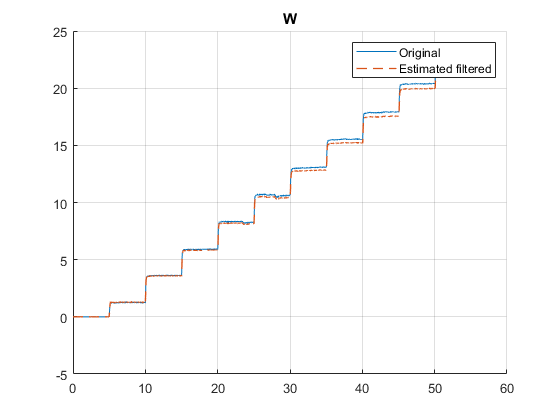


figure
hold on
plot(time(start:finish), w_orig(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 1, "LineStyle", "--")
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

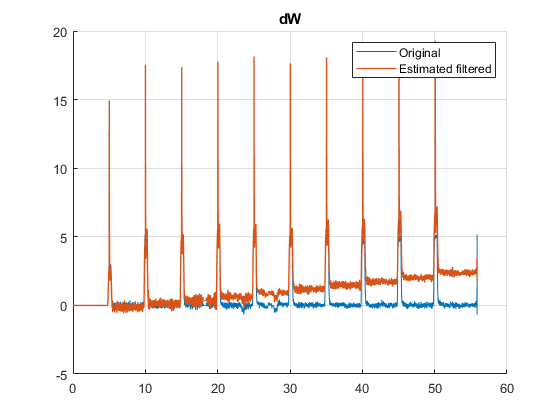


figure
hold on
plot(time(start:finish), dw_orig(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)), "LineWidth", 1)
hold off
grid on
title("dW")
xlim("auto")
ylim("auto")
% ylim([-60 60])
legend("Original", "Estimated filtered")

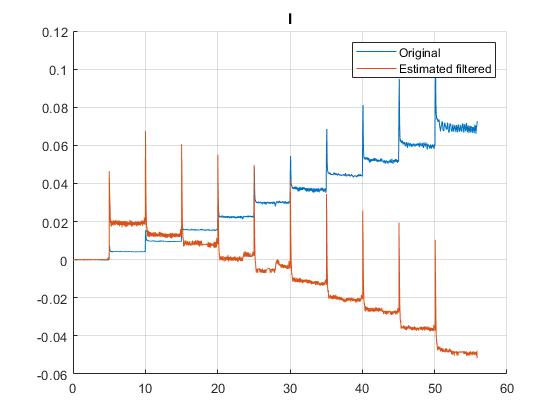


figure
hold on
plot(time(start:finish), current(start:finish))
plot(time(start:finish), x_arr(3, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")


figure
hold on
plot(time(start:finish), dI_arr(start:finish))
hold off
grid on
title("dI")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

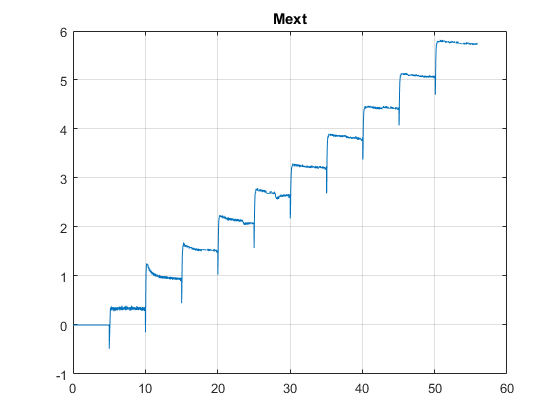


figure
plot(time, Mext_arr)
grid on
title("Mext")
xlim("auto")
ylim("auto")